ls = LightSim

ls =   LightSim with properties:

    col_wl_amp_spec: [300×404 double]
          spec_dark: [1×1 SpectrumClass]
          spec_1024: [1024×401 double]
          classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim'


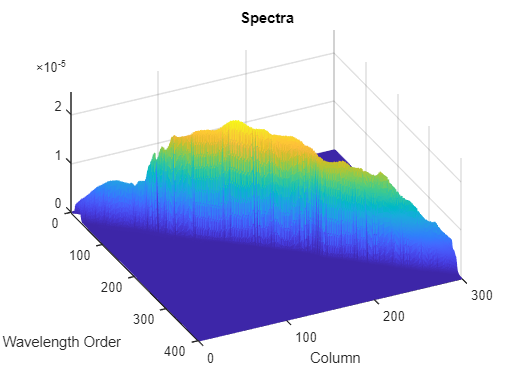


ls.check_data

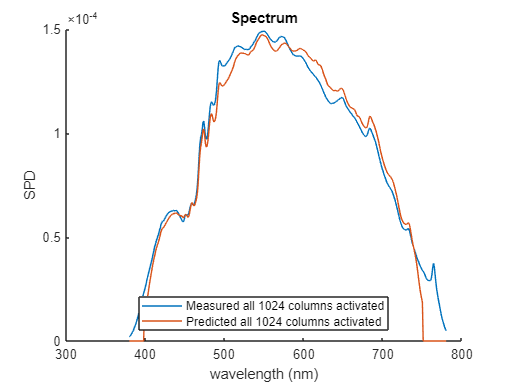


clf
hold on

load('C:\Users\wayne\Documents\GitHub\MIS_acquire\@OL490Class\ss.mat')
sall.plot

% plot(ls.col_wl_amp_spec(:,2),ls.col_wl_amp_spec(:,3)*7,'.')

s = ls.spec_1024;
ssum = sum(s,1);
plot(380:780,ssum*0.15)

legend('Measured all 1024 columns activated','Predicted all 1024 columns activated')
legend('Location','South')

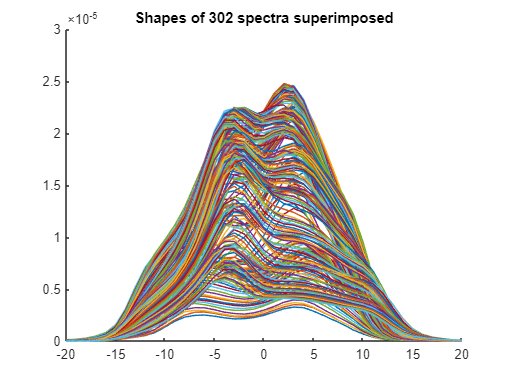

clf
hold on
for i = 1:length(ls.col_wl_amp_spec(:,1))
    x = ls.col_wl_amp_spec(i,2);
    spec = ls.col_wl_amp_spec(i,4:end);

    plot([380:780]-x,spec)
end
axis([-20 20 0 3e-5])
title('Shapes of 302 spectra superimposed')

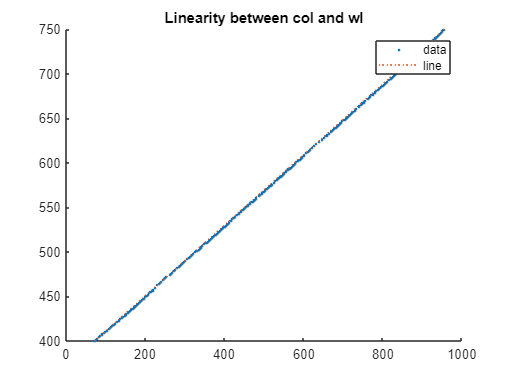

clf
hold on
plot(ls.col_wl_amp_spec(:,1),ls.col_wl_amp_spec(:,2),'.');
plot(ls.col_wl_amp_spec([1 end],1),ls.col_wl_amp_spec([1 end],2),':');
legend('data','line')
title('Linearity between col and wl')

clf
s = ls.spec_1024;
i = 157

i = 157

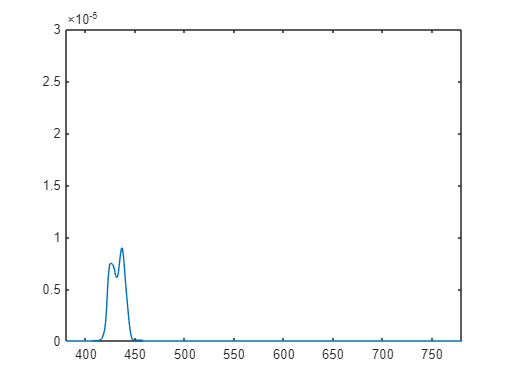

plot(380:780,s(i,:))
axis([380 780 0 3e-5])

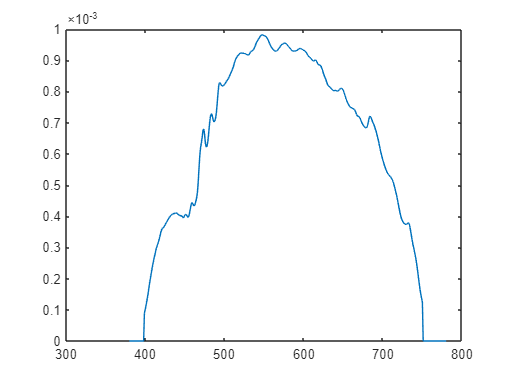

s = ls.spec_1024;
ssum = sum(s,1);
plot(380:780,ssum)

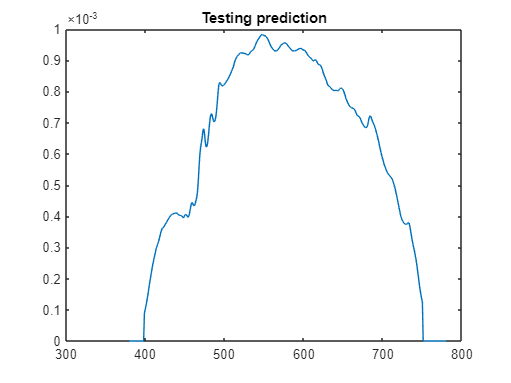

c_range = [1:1024];
c_vec = LightSim.multiple_peaks(c_range);
spec = ls.predict_vec_spec(c_vec);
clf
plot(380:780,spec)
title('Testing prediction')

i measured several spikes simultaneously to save time

i can find their peaks; but their valleys are mixed

so my model does not consider the valleys

then my model generates very off results when there is valley overlapping

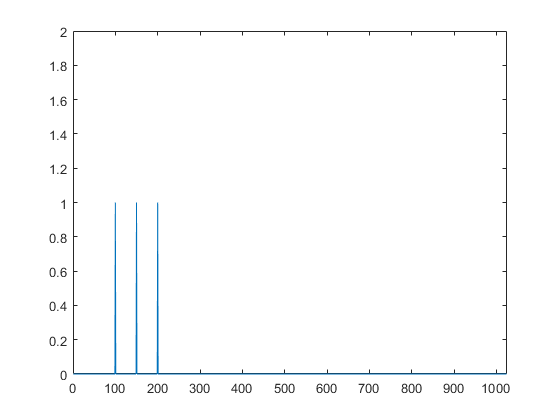

c_range = [100:50:200];
c_vec = LightSim.multiple_peaks(c_range);

clf
plot(c_vec)
axis([0 1025 0 2])

spec = ls.predict_vec_spec(c_vec);
%clf
%plot(380:780,spec)
%title('Testing prediction')
ol.setColumn1024(c_vec)
mea = cs.measure;

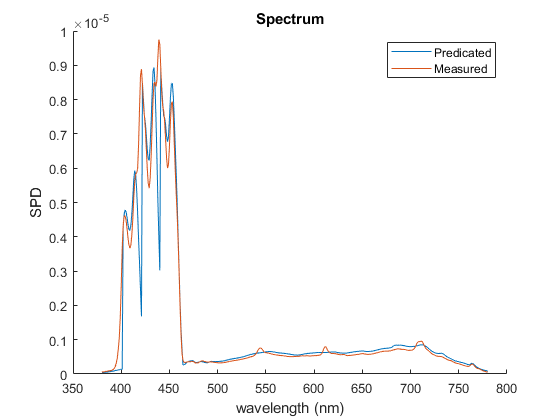


clf
hold on
plot(380:780,spec)
mea.plot
legend('Predicated','Measured')

ans = 'Solving M * A = B with R...'

ans = 0

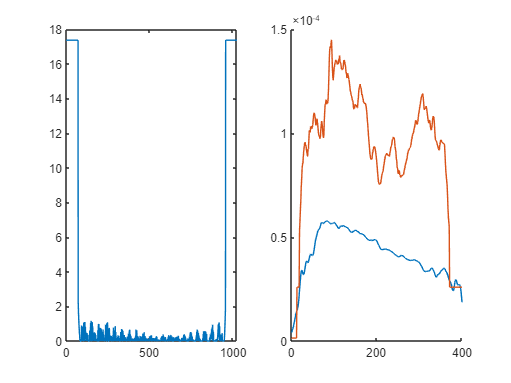

m = ls.spec_1024';
b = B*0.05;
r = Rsolver(m,b);

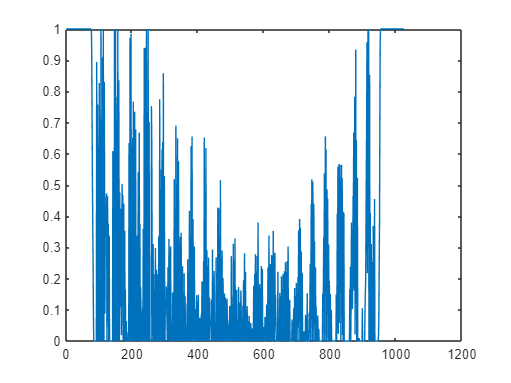

a = min(1,r.A);
clf
plot(a)

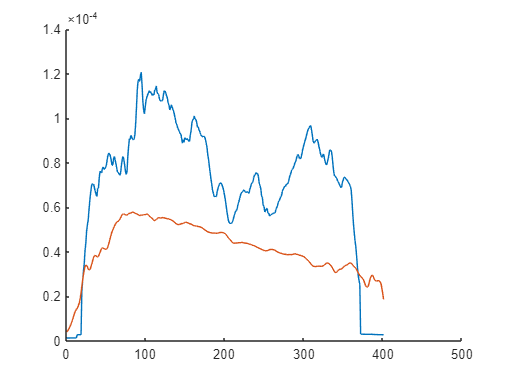

v = LightSim.multiple_peaks([100:10:1000]);
s = ls.predict_vec_spec(a);
clf
hold on
plot(s)
plot(b)